# Assignment 2

% Setup
clear
warning('off', 'MATLAB:paren:Useless');
tic
rng(10)
addpath('functions')
plotPos = [100 100 800, 400];



## Question 1.1

% Define sys:
s11.A = [1,-2.438, 1.942,-0.502];
s11.B = [1.446, -0.158, -1.093];
s11.C = [1, 0.5,0.75];
% Check stabilaty:
root = roots(s11.A) % Mag of complex eigs below 1, sys is internaly stable and therfore also BIBO stable.

root =     0.9511
    0.9012
    0.5856


abs(root)

ans =     0.9511
    0.9012
    0.5856


s11.sigma_e = 10^(-2);
s11.N = 360;
s11.k = 1;
n_max = max([length(s11.A),length(s11.B)]);
s11.u_init = zeros(n_max,1);
s11.y_init = 10*ones(n_max,1);

s11.e = normrnd(0, s11.sigma_e,s11.N,1);
T = s11.N/2; % Periode in sampels
s11.omega = 10*square(2*pi*1/T*(1:s11.N),50)';
s11.rho = 0.01;
[s11.y,s11.u] = MV0(s11.A, s11.B, s11.omega, s11.e, s11.N, s11.k, s11.y_init, s11.u_init);

% Define filename
filename = 'MV0.png';

% Call the function with your data structure `s11`
plotSystemResponse(s11, (1:s11.N), 1, plotPos, filename);


## Question 1.2

% Define sys:
s12.A = [1,-2.438, 1.942,-0.502];
s12.B = [1.446, -0.158, -1.093];
s12.C = [1, 0.5,0.75];
% Check stabilaty:
root = roots(s11.A) % Mag of complex eigs below 1, sys is internaly stable and therfore also BIBO stable.

root =     0.9511
    0.9012
    0.5856


abs(root)

ans =     0.9511
    0.9012
    0.5856


s12.sigma_e = 10^(-2);
s12.N = 360;
s12.k = 1;
n_max = max([length(s12.A),length(s12.B)]);
s12.u_init = zeros(n_max,1);
s12.y_init = 10*ones(n_max,1);
s12.theta_init = [s12.A(2:end), s12.B]';
s12.P_init = 0.001*eye(length(s12.theta_init ));


s12.e = normrnd(0, s12.sigma_e,s12.N,1);
T = s11.N/2; % Periode in sampels
s12.omega = 10*square(2*pi*1/T*(1:s12.N),50)';
s12.rho = 0.01;
[s12.y,s12.u] = MV0_RLS(s12.A, s12.B, s12.omega, s12.e, s12.N, s12.k, s12.y_init, s12.u_init, s12.theta_init, s12.P_init );

A_est_final = [1     -2.4379      1.9421    -0.50218]
B_est_final = [1.4461    -0.15792     -1.0929]



% Define filename
filename = 'MV0.png';

% Call the function with your data structure `s11`
plotSystemResponse(s12, (1:s12.N), 1, plotPos, filename);

## Question 1.3

% Define sys:
s13.A = [1,-2.438, 1.942,-0.502];
s13.B = [1.446, -0.158, -1.093];
% s13.C = [1, -1.441, 0.296, 0.167];
% Check stabilaty:
root = roots(s13.A) % Mag of complex eigs below 1, sys is internaly stable and therfore also BIBO stable.
abs(root)
s13.sigma_e = 10^(-2);
s13.N = 360;
s13.k = 1;
n_max = max([length(s13.A),length(s13.B)]);
s13.u_init = zeros(n_max,1);
s13.y_init = ones(n_max,1);
s13.theta_init = ones(size([s13.A(2:end), s13.B]'));
s13.P_init = 10*eye(length(s13.theta_init));

s13.e = normrnd(0, s13.sigma_e,s13.N,1);
T = s13.N/2; % Periode in sampels
s13.omega = 10*square(2*pi*1/T*(1:s13.N),50)';
s13.rho = 0.01;
[s13.y,s13.u] = MV0_RLS(s13.A, s13.B, s13.omega, s13.e, s13.N, s13.k, s13.y_init, s13.u_init, s13.theta_init, s13.P_init);

% Define filename
filename = 'MV0.png';

% Call the function with your data structure `s13`
plotSystemResponse(s13, (1:s13.N), 1, plotPos, filename);

## Question 2.2

rng(203829)
% Define sys:
s22.A = [1,-2.438, 1.942,-0.502];
s22.B = [1.446, -0.158, -1.093];
s22.C = [1, -1.441, 0.296, 0.167];
% Check stabilaty:
root = roots(s22.A) % Mag of complex eigs below 1, sys is internaly stable and therfore also BIBO stable.
abs(root)
s22.sigma_e = 10^(-2);

s22.N = 360;
s22.k = 1;
n_max = max([length(s22.A),length(s22.B),length(s22.C)]);
s22.u_init = zeros(n_max,1);
s22.y_init = ones(n_max,1);
s22.omega = zeros(1,s22.N);

lastwarn(''); % Clear last warning
s22.u = idinput(s22.N, 'prbs', [0 1], [-1 1]);
[msg, msgid] = lastwarn; % Get warning details
warning('off', msgid); % Suppress this warning


s22.e = normrnd(0, s22.sigma_e,s22.N,1);

[s22.y,s22.u] = ARMAX(s22.A, s22.B, s22.C, s22.k, s22.e, s22.N, s22.y_init, s22.u_init, s22.u);

% Define filename
filename = 'MV0.png';

% Call the function with your data structure `s22`
plotSystemResponse(s22, (1:s22.N), 0, plotPos, filename);

## Question 2.3

## Question 2.4

s24.A = [1,-2.438, 1.942,-0.502];
s24.B = [1.446, -0.158, -1.093];
s24.C = [1, -1.441, 0.296, 0.167];
s24.sigma_e = 10^(-2);
s24.N = 4*360;
s24.k = 1;
n_max = max([length(s24.A),length(s24.B), length(s24.C)]);



s24.e = normrnd(0, s24.sigma_e,s24.N,1);
T = s24.N/4; % Periode in sampels
s24.omega = 10*square(2*pi*1/T*(1:s24.N),50)';

s24.u_init = 0*ones(n_max,1);
s24.y_init = 0*ones(n_max,1);

Ay = 1;
By = 1; 
Au = 1; 
Bu = [1, -1]; % MV1a
Aw = 1; 
Bw = 1; 
rho = 7500; % MV1a

[s24.y,s24.u] = GMV(s24.A, s24.B, s24.C, s24.k, s24.omega,s24.e, s24.N, Ay, By, Au, Bu, Aw, Bw, rho,s24.y_init, s24.u_init);

% Define filename
filename = 'MV0.png';
s24.omega = filter(Bw,Aw,s24.omega);

% Call the function with your data structure `s11`
plotSystemResponse(s24, (1:s24.N), 1, plotPos, filename);

## Question 2.6

s23.A = [1, -2.438, 1.942, -0.502];
s23.B = [1.446, -0.158, -1.093];
s23.C = [1, -1.441, 0.296, 0.167];

na = numel(s23.A) - 1;
nb = numel(s23.B) - 1;
nc = numel(s23.C) - 1;

N = 360;
k = 1; % Input delay
u = s22.u;   % Input signal
e = 0.01 * randn(N,1); % Noise/disturbance
y_init = zeros(max([na, nb + k - 1, nc]), 1);
theta_init = [s23.A(2:end), s23.B, s23.C(2:end)]';
theta_init = ones(na + (nb + 1) + nc, 1);
P_init = 75 * eye(na + (nb + 1) + nc);

% Choose forgetting method: 'constant_gain' or 'exponential'
forgetting_method = 'exponential';  
% forgetting_method = 'constant_gain';
N_inf = 100;  % Horizon length for exponential forgetting
lambda = 1 - 1/N_inf;  % Forgetting factor for exponential method

[y, theta_rls] = armax_parameter_estimation(s23.A, s23.B, s23.C, u, e, N, y_init, theta_init, P_init, k, forgetting_method, lambda);
% Final estimated parameters
theta_final = theta_rls(:, end);
disp('Final estimated θ:');
disp(theta_final');

A_est = [1, theta_final(1:na)']
B_est = theta_final(na+1:na+1+nb)'
C_est = [1, theta_final(na+1+nb+1:end)']
disp((A_est-s23.A)/abs(max(s23.A))*100);
disp((B_est-s23.B)/abs(max(s23.B))*100);
disp((C_est-s23.C)/abs(max(s23.C))*100);



## Question 2.7

tic
clear
rng(10)
addpath('functions')
plotPos = [100 100 800, 400];
s27.A = [1, -2.438, 1.942, -0.502];
s27.B = [1.446, -0.158, -1.093];
s27.C = [1, -1.441, 0.296, 0.167];

na = numel(s27.A) - 1;
nb = numel(s27.B) - 1;
nc = numel(s27.C) - 1;

s27.N = 10*360;
s27.k = 1; % Input delay
 
s27.sigma_e = 10^(-2);
s27.e = normrnd(0, s27.sigma_e,s27.N,1);

n_max  = max([na, nb + s27.k - 1, nc]);
s27.y_init = zeros(n_max, 1);
s27.u_init = zeros(n_max,1);
theta_init = [s27.A(2:end), s27.B, s27.C(2:end)]';
theta_init = ones(na + (nb + 1) + nc, 1);
P_init = 100 * eye(na + (nb + 1) + nc);
T = s27.N/4; % Periode in sampels
s27.omega = 10*square(2*pi*1/T*(1:s27.N),50)';


% Choose forgetting method: 'constant_gain' or 'exponential'
forgetting_method = 'exponential';  
% forgetting_method = 'constant_gain';
N_inf = T;  % Horizon length for exponential forgetting
lambda = 1 - 1/N_inf;  % Forgetting factor for exponential method

Ay = 1;
By = 1; 
Au = 1; 
Bu = [1, -1]; % MV1a
Aw = 1; 
Bw = 1; 
rho = 500; % MV1a

[s27.y, s27.u, theta_rls] = MVa1_RLS(s27.A, s27.B, s27.C, s27.k, s27.omega,s27.e, s27.N,theta_init, P_init, Ay, By, Au, Bu, Aw, Bw, rho,s27.y_init, s27.u_init, forgetting_method, lambda);
% Final estimated parameters
theta_final = theta_rls(:, end);
disp('Final estimated θ:');

Final estimated θ:


disp(theta_final');

   -2.2363    1.6375   -0.3938    1.5218    0.0937   -0.9035   -1.2071    0.2212    0.0723




A_est = [1, theta_final(1:na)']

A_est =     1.0000   -2.2363    1.6375   -0.3938


B_est = theta_final(na+1:na+1+nb)'

B_est =     1.5218    0.0937   -0.9035


C_est = [1, theta_final(na+1+nb+1:end)']

C_est =     1.0000   -1.2071    0.2212    0.0723


disp((A_est-s27.A)/abs(max(s27.A))*100);

         0   10.3853  -15.6821    5.5706



disp((B_est-s27.B)/abs(max(s27.B))*100);

    5.2443   17.4086   13.1085



disp((C_est-s27.C)/abs(max(s27.C))*100);

         0   23.3938   -7.4799   -9.4706



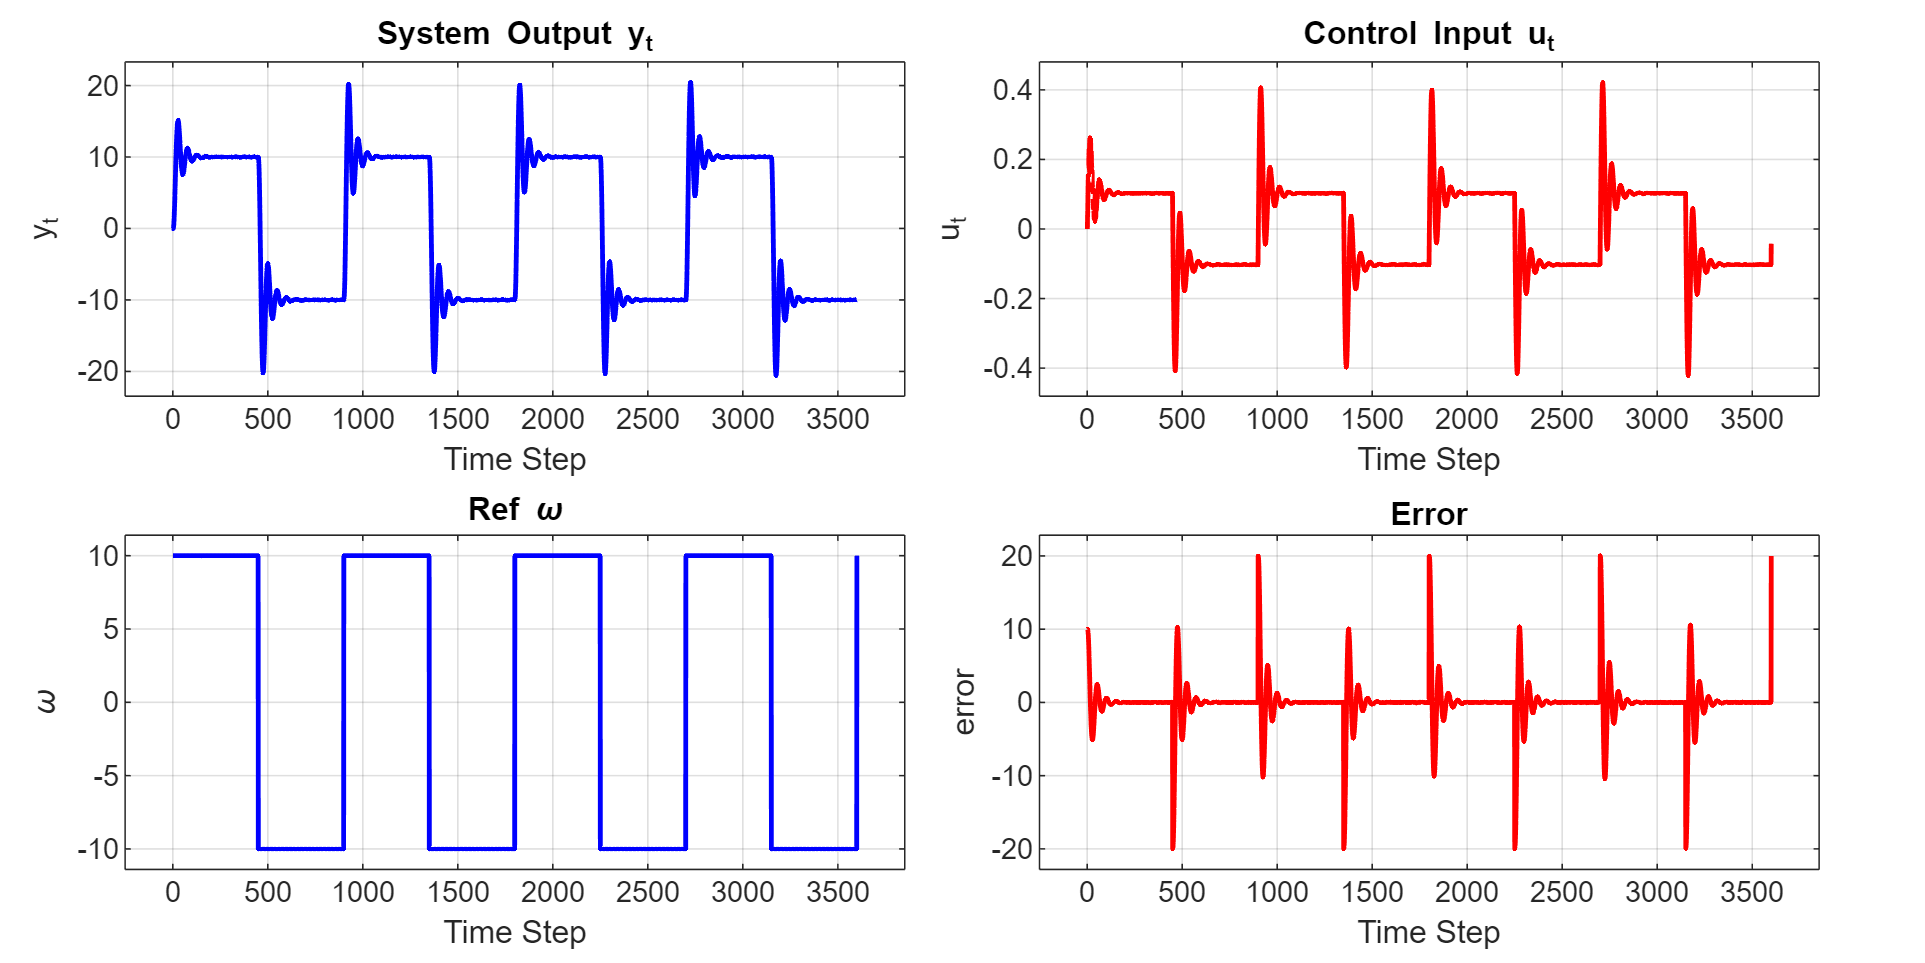


% Define filename
filename = 'MV0.png';

% Call the function with your data structure `s22`
plotSystemResponse(s27, (1:s27.N), 1, plotPos, filename);


toc

Elapsed time is 0.963157 seconds.
